%used to find the social interaction time during experimentation


%video name/ CHANGE EVERYTIME
a=WIN20190302150545ProfromS34853aggressivestranger32weeksDLCresne

a = 	1.0e+04 *

         0    0.1536    0.0531    0.0001    0.0856    0.0674    0.0000    0.0828    0.0681    0.0000    0.0851    0.0684    0.0000    0.0820    0.0693    0.0000    0.0847    0.0702    0.0000    0.0855    0.0699    0.0000    0.0766    0.0576    0.0000    0.1433    0.0447    0.0000    0.1430    0.0451    0.0001
    0.0001    0.1537    0.0531    0.0001    0.0767    0.0607    0.0000    0.0737    0.0579    0.0000    0.0797    0.0665    0.0000    0.0823    0.0689    0.0000    0.0820    0.0678    0.0000    0.0853    0.0679    0.0000    0.0856    0.0676    0.0000    0.1534    0.0527    0.0000    0.1430    0.0451    0.0001
    0.0002    0.1536    0.0532    0.0001    0.0848    0.0672    0.0000    0.0737    0.0579    0.0000    0.0796    0.0666    0.0000    0.0786    0.0676    0.0000    0.0807    0.0678    0.0000    0.0854    0.0679    0.0000    0.0840    0.0676    0.0000    0.1431    0.0449    0.0000    0.1433    0.0449    0.0001
    0.0003    0.1536    0.0533    0.0001    0.0857 

%frames of the video
frames=a(:,1);
 
%coordinates and likelihood of all dots
xn=a(:,2);
yn=a(:,3);
likenose=a(:,4);
 
xc1=a(:,5);
yc1=a(:,6);
likec1=a(:,7);
 
xc2=a(:,8);
yc2=a(:,9);
likec2=a(:,10);
 
xc3=a(:,11);
yc3=a(:,12);
likec3=a(:,13);
 
xc4=a(:,14);
yc4=a(:,15);
likec4=a(:,16);
 
xc5=a(:,17);
yc5=a(:,18);
likec5=a(:,19);
 
xc6=a(:,20);
yc6=a(:,21);
likec6=a(:,22);
 
xc7=a(:,23);
yc7=a(:,24);
likec7=a(:,25);
 
xc8=a(:,26);
yc8=a(:,27);
likec8=a(:,28);
 
xtail=a(:,29);
ytail=a(:,30);
liketail=a(:,31);
 
%distances from nose to circle
dnc1nose=sqrt((xn-xc1).^2 + (yn-yc1).^2);
dnc2nose=sqrt((xn-xc2).^2 + (yn-yc2).^2);
dnc3nose=sqrt((xn-xc3).^2 + (yn-yc3).^2);
dnc4nose=sqrt((xn-xc4).^2 + (yn-yc4).^2);
dnc5nose=sqrt((xn-xc5).^2 + (yn-yc5).^2);
dnc6nose=sqrt((xn-xc6).^2 + (yn-yc6).^2);
dnc7nose=sqrt((xn-xc7).^2 + (yn-yc7).^2);
dnc8nose=sqrt((xn-xc8).^2 + (yn-yc8).^2);
 
distancenose=[dnc1nose dnc2nose dnc3nose dnc4nose dnc5nose dnc6nose dnc7nose dnc8nose];
 
%distance from tail to circle
dnc1tail=sqrt((xtail-xc1).^2 + (ytail-yc1).^2);
dnc2tail=sqrt((xtail-xc2).^2 + (ytail-yc2).^2);
dnc3tail=sqrt((xtail-xc3).^2 + (ytail-yc3).^2);
dnc4tail=sqrt((xtail-xc4).^2 + (ytail-yc4).^2);
dnc5tail=sqrt((xtail-xc5).^2 + (ytail-yc5).^2);
dnc6tail=sqrt((xtail-xc6).^2 + (ytail-yc6).^2);
dnc7tail=sqrt((xtail-xc7).^2 + (ytail-yc7).^2);
dnc8tail=sqrt((xtail-xc8).^2 + (ytail-yc8).^2);
 
distancetail=[dnc1tail dnc2tail dnc3tail dnc4tail dnc5tail dnc6tail dnc7tail dnc8tail];
 
%minimum distance that is found between nose and a circle and plot
Mnose=min(distancenose,[],2);
%plot(frames,Mnose);
 
%minimum distance that is found between tail and a circle and plot
Mtail=min(distancetail,[],2);
%plot(frames,Mtail);
 
 
%removal of values we do not want while still keeping the original index
compact=[frames Mnose likenose];
compact2= [frames Mtail liketail];
 
%Circle likelihoods all in one thing
circlelike= [frames likec1 likec2 likec3 likec4 likec5 likec6 likec7 likec8];
 
%if nose distance is greater than tail distance make the distance zero
for i=1:frames
   if compact(i,2)>compact2(i,2)
       compact(i,2)=0;
   end
   if circlelike(:,2)<0.1
       compact(i,2)=0;
   end
   if circlelike(:,3)<0.1
       compact(i,2)=0;
   end
   if circlelike(:,4)<0.1
       compact(i,2)=0;
   end
   if circlelike(:,5)<0.1
       compact(i,2)=0;
   end
   if circlelike(:,6)<0.1
       compact(i,2)=0;
   end
   if circlelike(:,7)<0.1
       compact(i,2)=0;
   end
   if circlelike(:,8)<0.1
       compact(i,2)=0;
   end
   if compact2(:,3)<0.1
       compact(i,2)=0;
   end
end


 
%removing labels that have low possibility of being there
Findnose=compact(:,3)<0.10; %find all cases where the nose likelihood is less than 0.1
compact(Findnose,:)=[]; %make all values in a row zero when the nose likelihood is less than 0.1
%bar(compact(:,1),compact(:,2)); %plot of frames verses the minimum distance between nose and circle
 
%Findtail=compact2(:,3)<0.10; %find all cases where the tail likelihood is less than 0.1
%compact(Findtail,:)=[]; %make all values in a row zero when the tail likelihood is less than 0.1
%bar(compact(:,1),compact(:,2)); %plot of frames verses the minimum distance between tail and circle
 
FindThreshnose=compact(:,2)>30; %find values where the distance is greater than the value
compact(FindThreshnose,:)=[]; %make zero all rows where the value is greater than the value
%bar(compact(:,1),compact(:,2)); %plot of frames verses minimum distance between nose and circle
 
 
takeawayzero=compact(:,2)== 0;
compact(takeawayzero,:)=[];
%bar(compact(:,1),compact(:,2));
 
%turning remaining frames into a time in order to determine amount of social time.
timeoftotalvidsec=554 %NEEDS TO BE CHANGED EVERYTIME

timeoftotalvidsec = 554

interactStartSec=50 %NEEDS TO BE CHNAGED EVERYTIME

interactStartSec = 50

framespersec= length(frames)/timeoftotalvidsec

framespersec = 29.8285

socialtime=length(compact)/framespersec

socialtime = 216.1019

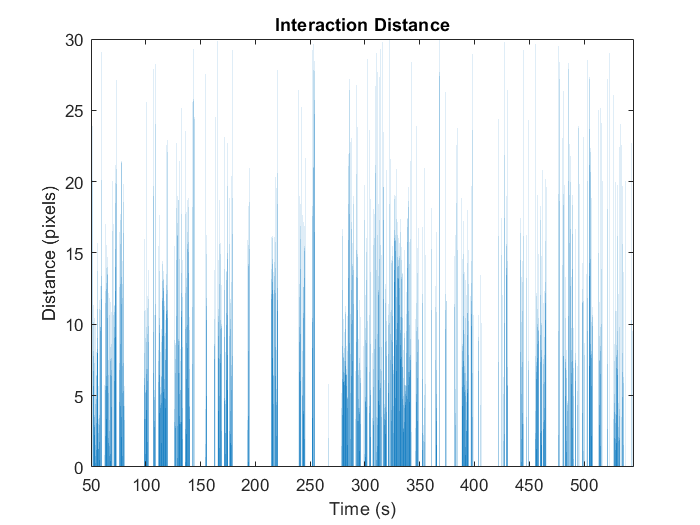


timetosec= (compact(:,1)/framespersec); 
beforeInteraction=timetosec < interactStartSec; %find values where the distance is greater than the value
compact(beforeInteraction,:)=[];
timetosec(beforeInteraction) = [];

figure(1);
bar(timetosec, compact(:,2));
title("Interaction Distance")
xlabel("Time (s)")
ylabel("Distance (pixels)")

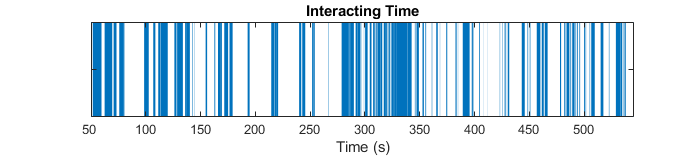


fig = figure(3);
times = compact(:,1);
prev = times(1);
bars = [];
prevBlock = 0;
counter = 0;
for idx = 2:length(times)
    val = times(idx);
    if val - prev <= 1
        counter = counter+1;
        prev = val;
        prevBlock = 0;
    else
        if counter > 0
            bars = [bars counter/framespersec];
        end
        if prevBlock == 0
            bars = [bars (val-prev)/framespersec];
            prevBlock = 1;
        else
            bars = [bars 1/framespersec (val-prev)/framespersec];
        end
        
        prev = val;
        counter = 0;
    end
end
bars = [interactStartSec bars];

bh = barh([1], bars, 'stacked', "EdgeColor", "none");
set(bh, 'FaceColor', 'Flat');
colors = zeros(length(bh)-1, 3);
interactions = zeros(1,length(bars));
if times(3) - times(2) > 1
    flipper = -1;
else
    flipper = 1;
end
for idx = 2:length(bh)
    if flipper == 1
        colors(idx-1,:) = [0 0.4470 0.7410];
        interactions(idx-1) = 1;
    else
        colors(idx-1,:) = [1 1 1];
        interactions(idx-1) = 0;
    end
    flipper = flipper * -1;   
end
colors = [[1 1 1]; colors];
colors = mat2cell(colors, ones(numel(bh),1), 3);

set(bh, {'CData'}, colors);
ylim([0.6 1.4]);
xlim([interactStartSec max(times)/framespersec]);
fig.Position = [10 10 560 125];
set(gca,'yticklabel',[]);
set(gca,'xticklabel', [50*round(interactStartSec/50):50:(timeoftotalvidsec-50)])
title("Interacting Time");
xlabel("Time (s)");


timeStamps = zeros(1,length(bars));
curTime = bars(1);
for idx = 2:length(bars)
    timeStamps(idx-1) = curTime;
    curTime = curTime + bars(idx);
end

stampsAndInteractions = [timeStamps' interactions']

stampsAndInteractions =    50.0000    1.0000
   50.8046         0
   51.5421    1.0000
   59.6217         0
   59.7558    1.0000
   59.8563         0
   62.4378    1.0000
   69.3774         0
   70.6849    1.0000
   73.2998         0


writematrix(stampsAndInteractions,'interactions.csv') 

Results=[timetosec compact(:,2)];

Error using horzcat
Dimensions of arrays being concatenated are not consistent.